Procesando: .\Imagenes\4.2.03.png


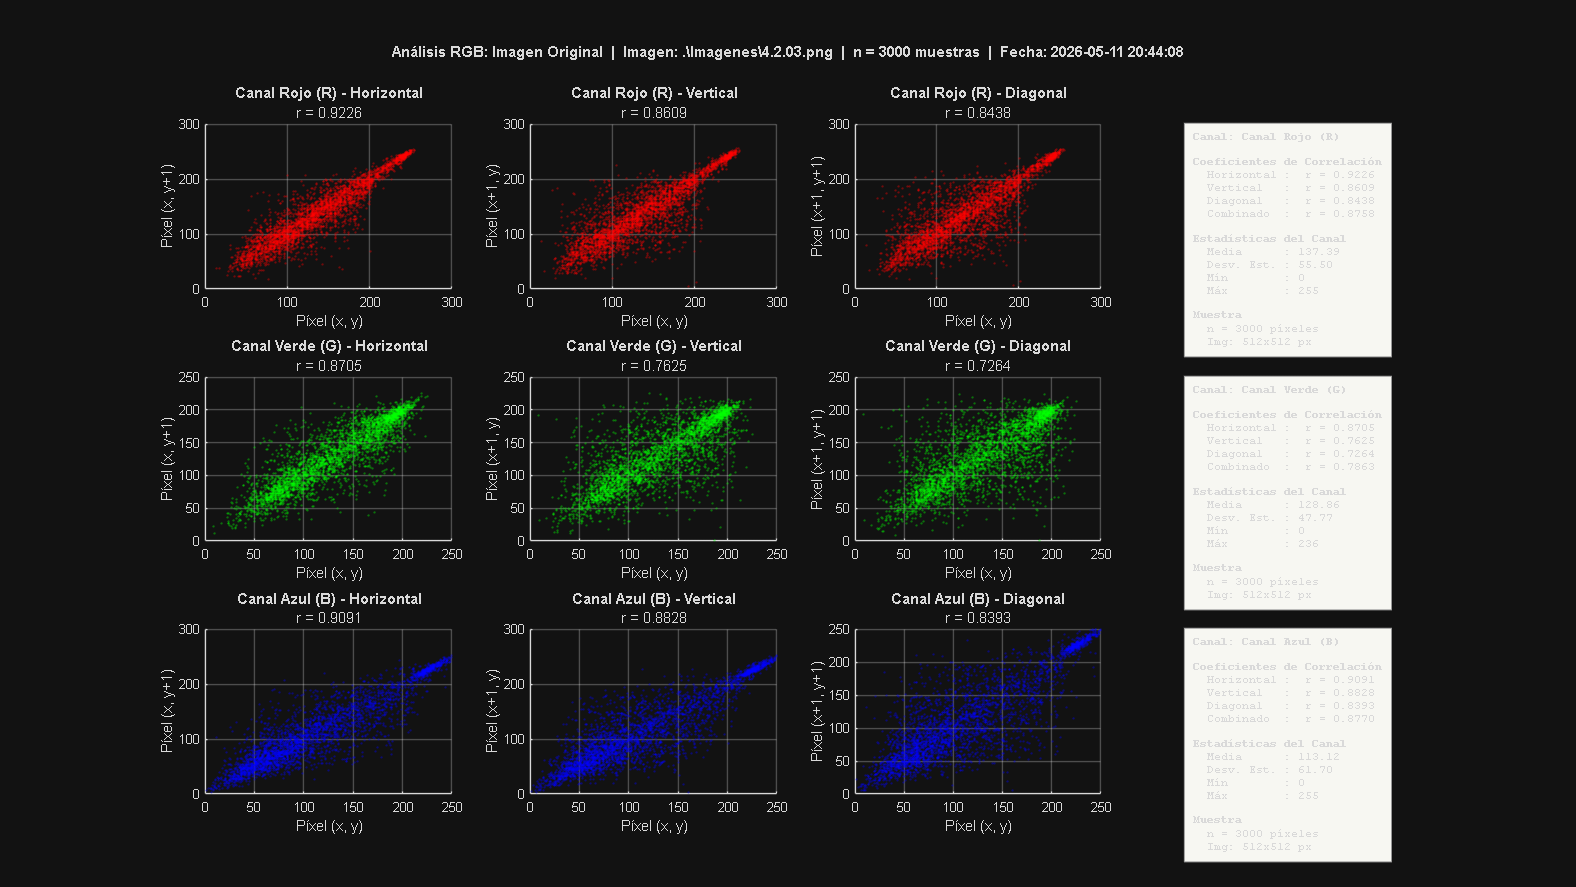

✔ PDF exportado: RGB_Original_20260511_204409.pdf


Procesando: .\Imagenes\cifrado.png


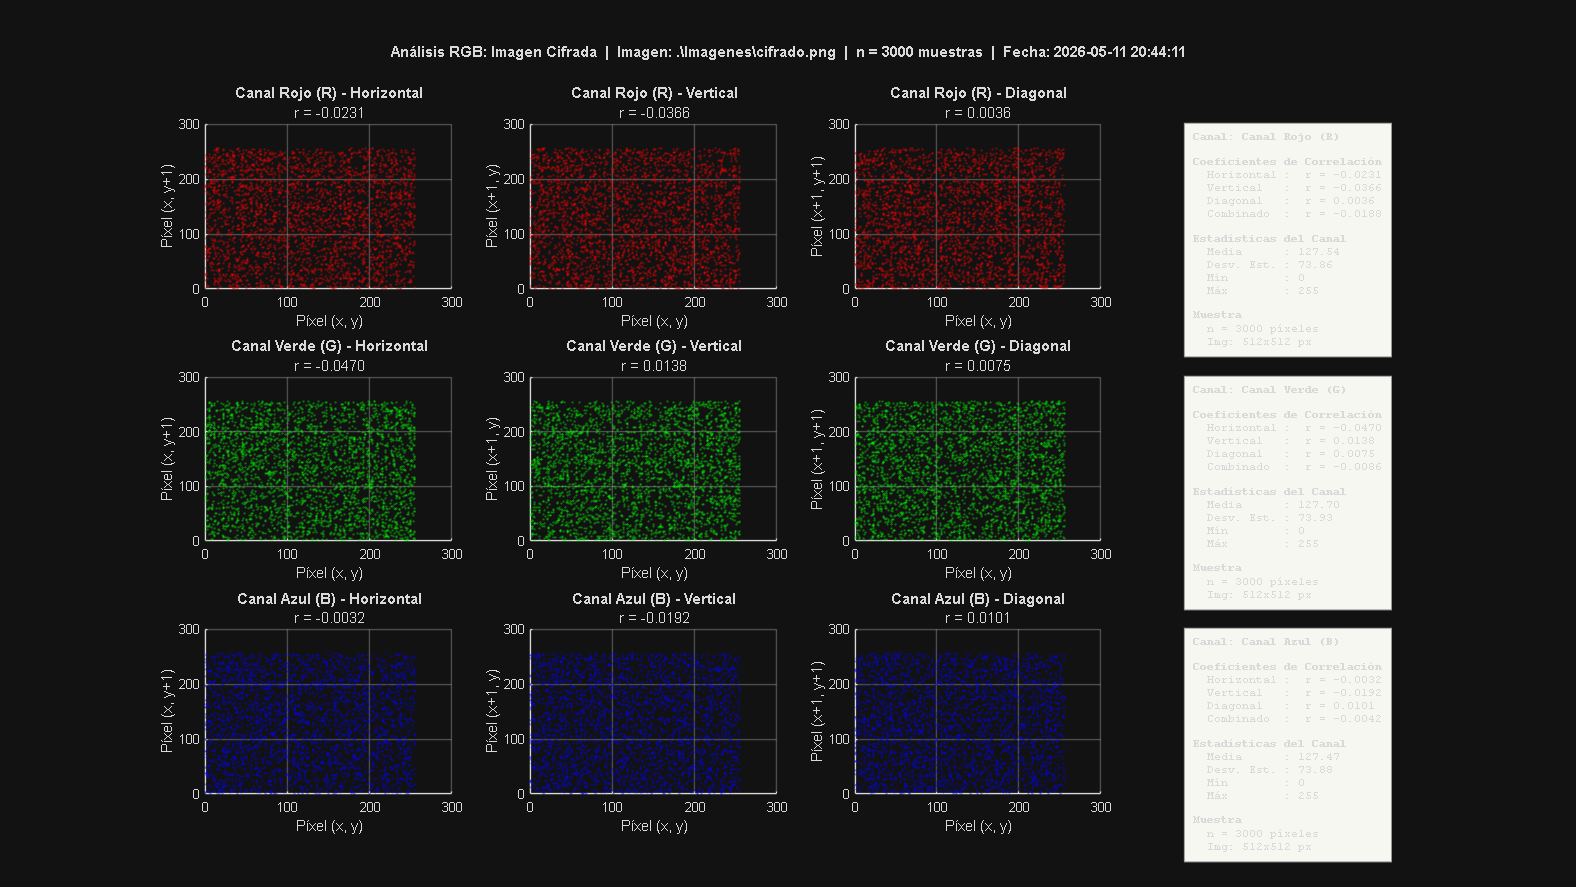

✔ PDF exportado: RGB_Cifrada_20260511_204411.pdf


% ---------------------------------------------------------
% Análisis de Correlación RGB: Imagen Original vs Cifrada
% ---------------------------------------------------------

rutas = {'.\Imagenes\4.2.03.png', '.\Imagenes\cifrado.png'};
nombres_fig = {'Análisis RGB: Imagen Original', 'Análisis RGB: Imagen Cifrada'};
nombres_archivos_pdf = {'RGB_Original', 'RGB_Cifrada'};
nombres_canales = {'Canal Rojo (R)', 'Canal Verde (G)', 'Canal Azul (B)'};
colores = {'r', 'g', 'b'};

% 1. INTERACTIVE SAMPLE SIZE (n)
n_samples = 3000;

for i = 1:2
    filePath = rutas{i};
    if exist(filePath, 'file')
        disp(['Procesando: ', filePath]);
        img = imread(filePath);
    else
        disp(['Error: No se encontró ', filePath, '. Usando peppers.png.']);
        img = imread('peppers.png');
    end

    if size(img, 3) == 1
        disp('Advertencia: Imagen en escala de grises. Se replicará en 3 canales.');
        img = cat(3, img, img, img);
    end

    img = double(img);
    [rows, cols, ~] = size(img);

    max_possible = (rows-1) * (cols-1);
    n = min(n_samples, max_possible);

    % Coordenadas aleatorias (semilla fija para reproducibilidad)
    rng(42);
    rand_rows = randi([1, rows-1], n, 1);
    rand_cols = randi([1, cols-1], n, 1);
    idx_base = sub2ind([rows, cols], rand_rows, rand_cols);
    idx_horz = sub2ind([rows, cols], rand_rows, rand_cols + 1);
    idx_vert = sub2ind([rows, cols], rand_rows + 1, rand_cols);
    idx_diag = sub2ind([rows, cols], rand_rows + 1, rand_cols + 1);

    % Figura principal
    fig = figure('Name', nombres_fig{i}, 'Position', [50, 50, 1600, 900]);

    % === SGTITLE CON METADATOS GLOBALES ===
    fecha_hora = datestr(now, 'yyyy-mm-dd HH:MM:SS');
    sgtitle(sprintf('%s  |  Imagen: %s  |  n = %d muestras  |  Fecha: %s', ...
        nombres_fig{i}, filePath, n, fecha_hora), ...
        'FontSize', 11, 'FontWeight', 'bold', 'Interpreter', 'none');

    % Tabla resumen acumulada (para el panel de estadísticas)
    stats_tabla = cell(3, 4); % [canal x {r_horz, r_vert, r_diag, r_comp}]

    for c = 1:3
        canal = img(:,:,c);
        x_val  = canal(idx_base);
        y_horz = canal(idx_horz);
        y_vert = canal(idx_vert);
        y_diag = canal(idx_diag);

        % Coeficientes
        r_horz = corr2d(x_val, y_horz);
        r_vert = corr2d(x_val, y_vert);
        r_diag = corr2d(x_val, y_diag);
        x_all  = [x_val; x_val; x_val];
        y_all  = [y_horz; y_vert; y_diag];
        r_comp = corr2d(x_all, y_all);

        stats_tabla{c,1} = r_horz;
        stats_tabla{c,2} = r_vert;
        stats_tabla{c,3} = r_diag;
        stats_tabla{c,4} = r_comp;

        % --- Horizontal ---
        subplot(3, 4, (c-1)*4 + 1);
        scatter(x_val, y_horz, 3, colores{c}, 'filled', 'MarkerFaceAlpha', 0.4);
        title(sprintf('%s - Horizontal', nombres_canales{c}));
        xlabel('Píxel (x, y)'); ylabel('Píxel (x, y+1)');
        subtitle(sprintf('r = %.4f', r_horz));
        grid on;

        % --- Vertical ---
        subplot(3, 4, (c-1)*4 + 2);
        scatter(x_val, y_vert, 3, colores{c}, 'filled', 'MarkerFaceAlpha', 0.4);
        title(sprintf('%s - Vertical', nombres_canales{c}));
        xlabel('Píxel (x, y)'); ylabel('Píxel (x+1, y)');
        subtitle(sprintf('r = %.4f', r_vert));
        grid on;

        % --- Diagonal ---
        subplot(3, 4, (c-1)*4 + 3);
        scatter(x_val, y_diag, 3, colores{c}, 'filled', 'MarkerFaceAlpha', 0.4);
        title(sprintf('%s - Diagonal', nombres_canales{c}));
        xlabel('Píxel (x, y)'); ylabel('Píxel (x+1, y+1)');
        subtitle(sprintf('r = %.4f', r_diag));
        grid on;

        % === PANEL DE ESTADÍSTICAS (reemplaza scatter "Completa") ===
        ax_info = subplot(3, 4, (c-1)*4 + 4);
        set(ax_info, 'Visible', 'off'); % Ocultar ejes

        % Calcular media, desv. estándar del canal
        media_canal  = mean(canal(:));
        std_canal    = std(canal(:));
        min_canal    = min(canal(:));
        max_canal    = max(canal(:));

        info_texto = sprintf([ ...
            '\\bfCanal: %s\\rm\n\n' ...
            '\\bfCoeficientes de Correlación\\rm\n' ...
            '  Horizontal :  r = %.4f\n' ...
            '  Vertical   :  r = %.4f\n' ...
            '  Diagonal   :  r = %.4f\n' ...
            '  Combinado  :  r = %.4f\n\n' ...
            '\\bfEstadísticas del Canal\\rm\n' ...
            '  Media      : %.2f\n' ...
            '  Desv. Est. : %.2f\n' ...
            '  Mín        : %.0f\n' ...
            '  Máx        : %.0f\n\n' ...
            '\\bfMuestra\\rm\n' ...
            '  n = %d píxeles\n' ...
            '  Img: %dx%d px'], ...
            nombres_canales{c}, ...
            r_horz, r_vert, r_diag, r_comp, ...
            media_canal, std_canal, min_canal, max_canal, ...
            n, rows, cols);

        text(0.05, 0.95, info_texto, ...
            'Units', 'normalized', ...
            'VerticalAlignment', 'top', ...
            'FontSize', 8.5, ...
            'FontName', 'Courier New', ... % Fuente monoespaciada → alineación
            'BackgroundColor', [0.97 0.97 0.95], ...
            'EdgeColor', [0.6 0.6 0.6], ...
            'Margin', 6, ...
            'Interpreter', 'tex', ...
            'Parent', ax_info);

        title(ax_info, sprintf('%s - Resumen', nombres_canales{c}));
    end

    % Ajustar espaciado para que el sgtitle no colisione
    set(fig, 'Units', 'normalized');
    tightfig_margin = 0.04;
    annotation(fig, 'rectangle', [0 0 1 1], 'Color', 'none'); % fuerza render

    % === EXPORTAR A PDF ===
    pdf_nombre = sprintf('%s_%s.pdf', nombres_archivos_pdf{i}, datestr(now, 'yyyymmdd_HHMMSS'));
    print(fig, pdf_nombre, '-dpdf', '-bestfit', '-r150');
    disp(['✔ PDF exportado: ', pdf_nombre]);
end


% -------------------------------------------------------
% Función auxiliar: correlación entre dos vectores
% (equivalente a corrcoef pero retorna solo el escalar)
% -------------------------------------------------------
function r = corr2d(a, b)
    C = corrcoef(a(:), b(:));
    r = C(1,2);
end